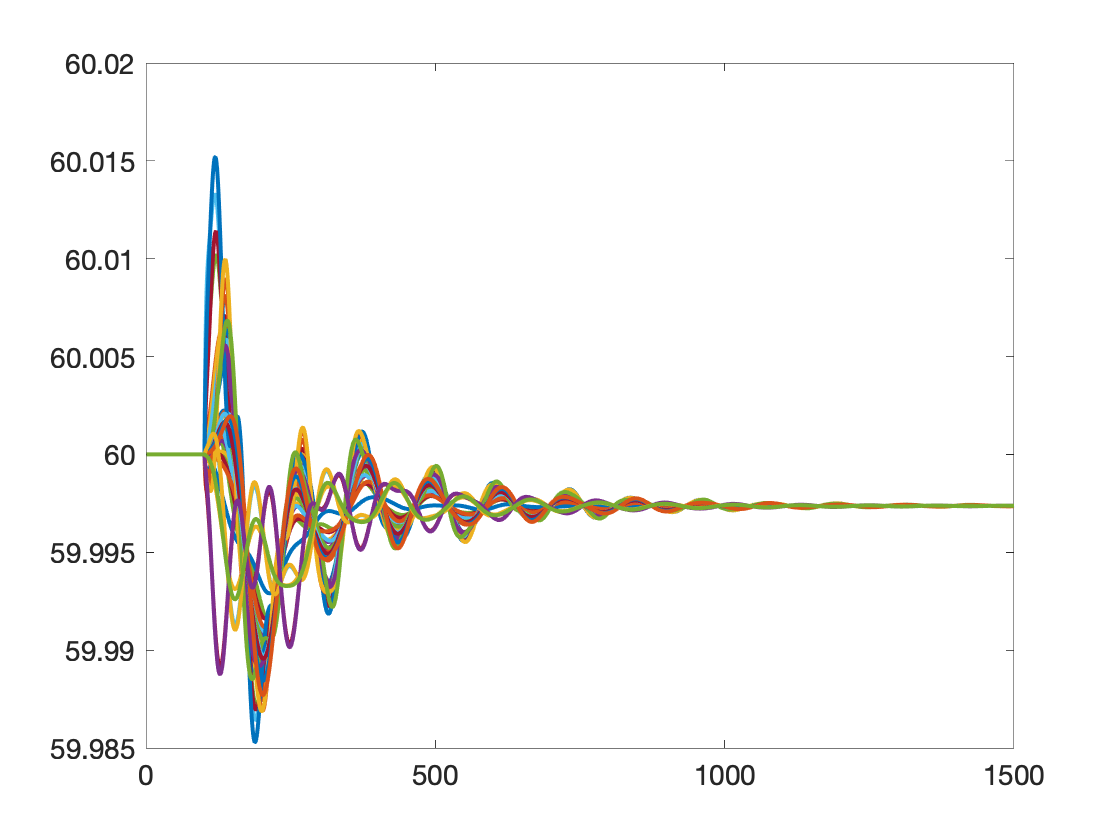

load(sprintf('/Users/nand311/Repositories/GridSTAGE/code/Results/IEEE68busSystem/LoadChanges/scenario10/PMUData.mat'))
figure
plot(PMU.f,'LineWidth',2)

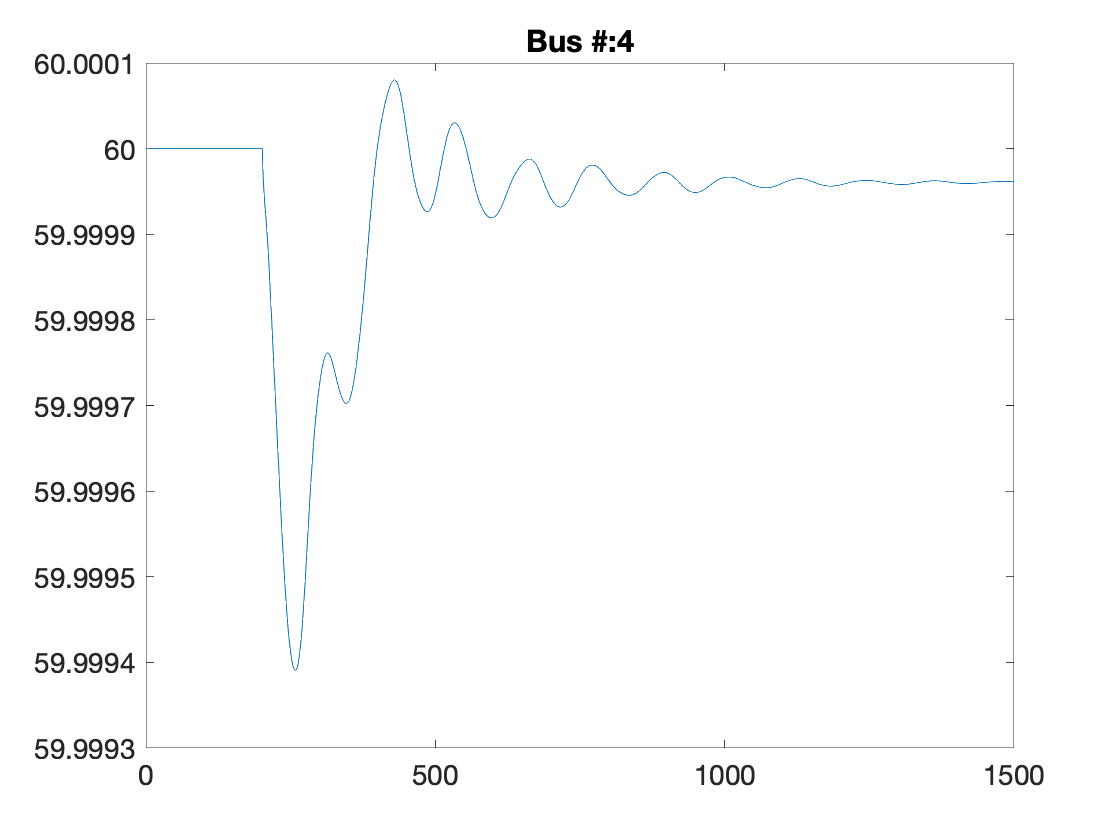

figure
for i = 1:68
    plot(PMU.f(:,i),'LineWidth',2)
    title(sprintf('Bus :%d',i))   
    ylim([59.99 60.01])
    pause
end

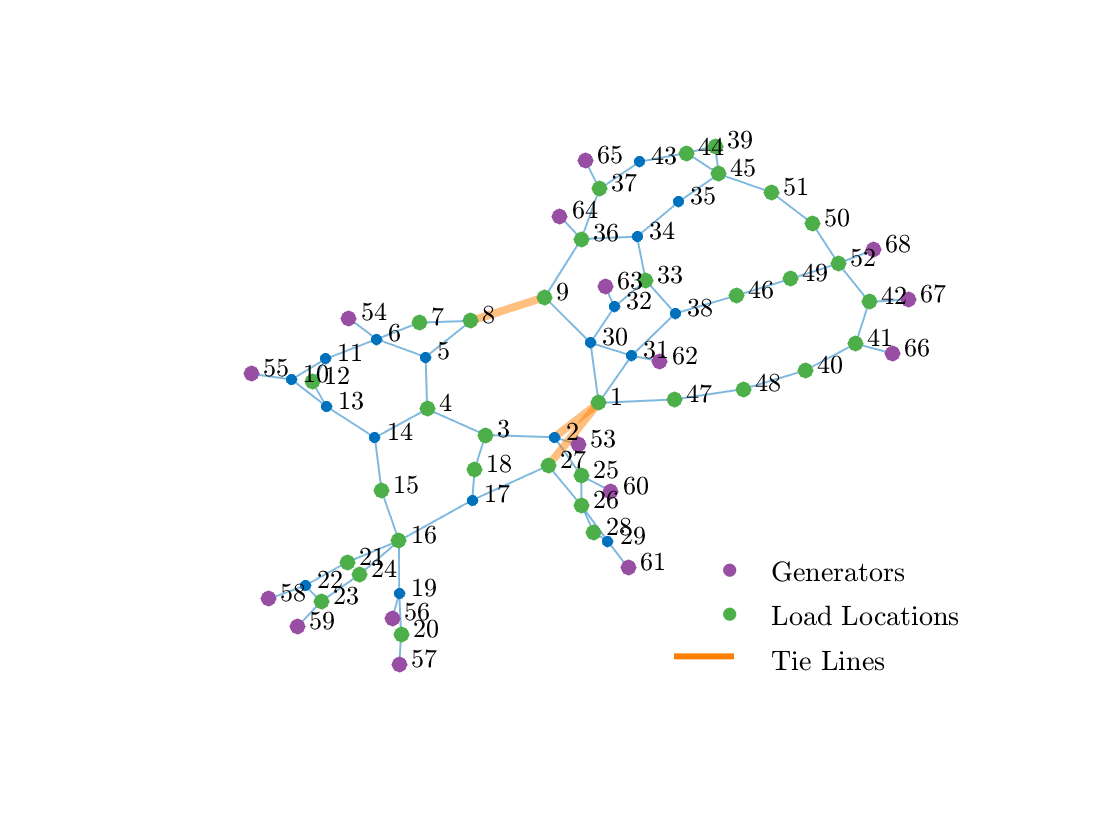

CurResDir = '/Users/nand311/Repositories/GridSTAGE/code/Results/IEEE68busSystem';
load(sprintf('%s/TopologyData',CurResDir))
G = graph(A);
figure
h1 = plot(G1, 'MarkerSize',5,'LineWidth',LWidths); hold on
if ~isempty(generator_locations)
    highlight(h1, generator_locations, 'NodeColor', map(4,:), 'MarkerSize',7)
end
if ~isempty(TieLines)
    for i = 1:size(TieLines,1)
        highlight(h1, TieLines(i,1), TieLines(i,2), 'EdgeColor', map(5,:))
    end
end
% highlight(h1, 17, 18, 'EdgeColor', color2)
% if ~isempty(PMU_locations)
%     highlight(h1, PMU_locations, 'NodeColor',map(3,:),'MarkerSize',7)
% end
% if ~isempty(attack_locations)
%     highlight(h1, attack_locations, 'NodeColor', map(1,:), 'MarkerSize',7)
% end
if ~isempty(load_locations)
    highlight(h1, load_locations, 'NodeColor', map(3,:), 'MarkerSize',7)
end
% set(gca,'xtick',[])
% set(gca,'ytick',[])
nl = h1.NodeLabel;
h1.NodeLabel = '';
xd = get(h1, 'XData');
yd = get(h1, 'YData');
text(xd+0.12, yd+0.05, nl, 'FontSize',13)

text(1.6, -2.2,'.','FontSize',60,'color',map(4,:))
text(2.2, -2.55,'Generators','FontSize',14)
text(1.6, -2.8,'.','FontSize',60,'color',map(3,:))
text(2.2, -3.15,'Load Locations','FontSize',14)
text(1.2, -2.9,'_','FontSize',60,'color',map(5,:))
text(2.2, -3.75,'Tie Lines','FontSize',14)
% text(1.6, -3.8,'_','FontSize',50,'color',map(5,:))
% text(2.2, -4.4,'Tie Lines','FontSize',14)

set(gca,'Visible','off')

% nearest(G,64,1) % Gives all 1 hop buses only
% setdiff(nearest(G,64,2),nearest(G,64,1)) % Gives all 2 hops buses only
% setdiff(nearest(G,64,3),nearest(G,64,2)) % Gives all 3 hops buses only
% setdiff(nearest(G,64,4),nearest(G,64,3)) % Gives all 4 hops buses only

buses_1_hop = [];
buses_2_hop = [];
buses_3_hop = [];
buses_4_hop = [];

for i_gen = 1:1 %length(generator_locations)
    generator_locations(i_gen)
    nearest(G,generator_locations(i_gen),1)
    setdiff(nearest(G,generator_locations(i_gen),2),nearest(G,generator_locations(i_gen),1))
    setdiff(nearest(G,generator_locations(i_gen),3),nearest(G,generator_locations(i_gen),2))
    % Gives all 1 hop buses only
%     buses_1_hop = [buses_1_hop; intersect(nearest(G,generator_locations(i_gen),1), load_locations)];
%     % Gives all 2 hops buses only
%     buses_2_hop = [buses_2_hop; intersect(setdiff(nearest(G,generator_locations(i_gen),2),nearest(G,generator_locations(i_gen),1)), load_locations)]; 
%     % Gives all 3 hops buses only
%     buses_3_hop = [buses_3_hop; intersect(setdiff(nearest(G,generator_locations(i_gen),3),nearest(G,generator_locations(i_gen),2)), load_locations)];  
%     % Gives all 4 hops buses only
%     buses_4_hop = [buses_4_hop; intersect(setdiff(nearest(G,generator_locations(i_gen),4),nearest(G,generator_locations(i_gen),3)), load_locations)]; 
end

ans = 53

ans = 2

ans =      1
     3
    25


ans =      4
    18
    26
    27
    30
    31
    47
    60
